%Create datastores
e2eDir = fullfile('.','Images');
imds = imageDatastore(e2eDir);
imds = shuffle(imds);
%create partitions
count = 100;(length(dir(e2eDir))-2)/2

ans = 5.0128e+04

trainCount = round(count*.75)

trainCount = 75

testCount = round(count*.8)

testCount = 80

imdsTrain = subset(imds,[1:trainCount]);
imdsVal = subset(imds,[trainCount+1:testCount]);
imdsTest = subset(imds,[testCount+1:count]);
%create syntetic blur
dsTrainNoisy = transform(imdsTrain,@addNoise);
dsValNoisy = transform(imdsVal,@addNoise);
dsTestNoisy = transform(imdsTest,@addNoise);
%combine input and label
dsTrain = combine(dsTrainNoisy,imdsTrain);
dsVal = combine(dsValNoisy,imdsVal);
dsTest = combine(dsTestNoisy,imdsTest);

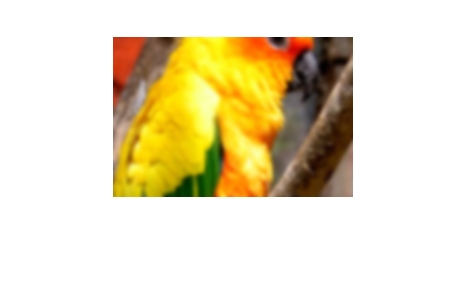

blurImg = dsTrainNoisy.read();    
imshow(blurImg)

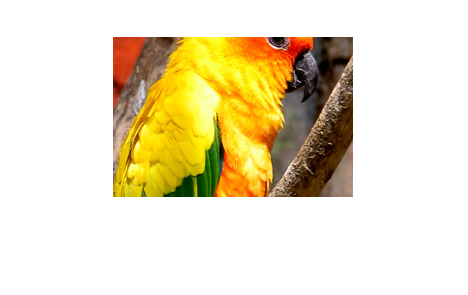

trueImg = imdsTrain.read();
imshow(trueImg)

lgraph = unetLayers([160 240 3] , 3,'encoderDepth',3);
lgraph = lgraph.removeLayers('Softmax-Layer');
lgraph = lgraph.removeLayers('Segmentation-Layer');
lgraph = lgraph.addLayers(regressionLayer('name','regressionOutput'));
lgraph = lgraph.connectLayers('Final-ConvolutionLayer','regressionOutput');
maxEpochs = 1;
epochIntervals = 1;
initLearningRate = 0.1;
learningRateFactor = 0.1;
l2reg = 0.0001;
options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',2, ...
    'Shuffle','never', ...
    'Plots','training-progress', ...
    'Verbose',false);
net = trainNetwork(dsTrain,lgraph,options);
modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');

%save(['E2E trainedNet-' modelDateTime '-Epoch-' num2str(maxEpochs*epochIntervals) ...
%            'ScaleFactors-' num2str(234) '.mat'],'net','options');

testTrue = imageDatastore(fullfile('TestImages','True'));
testBlur = imageDatastore(fullfile('TestImages','Blur'));

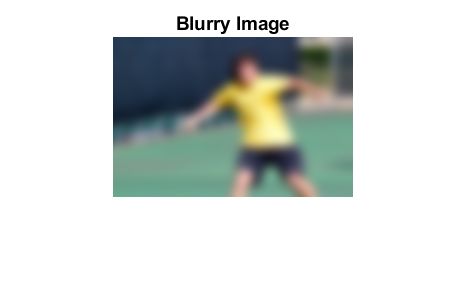

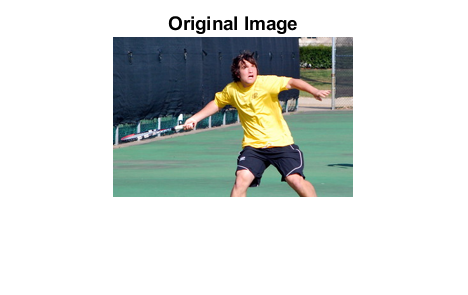

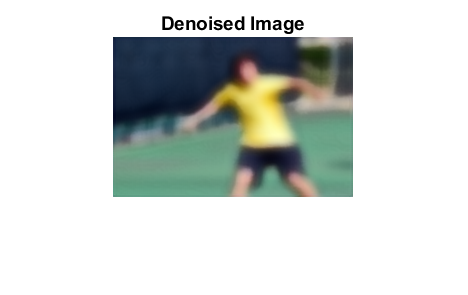

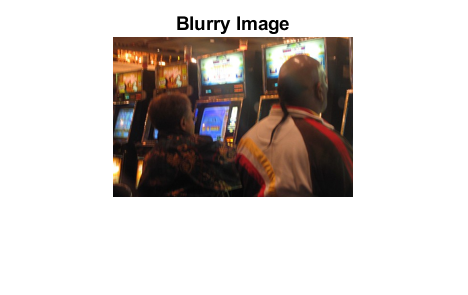

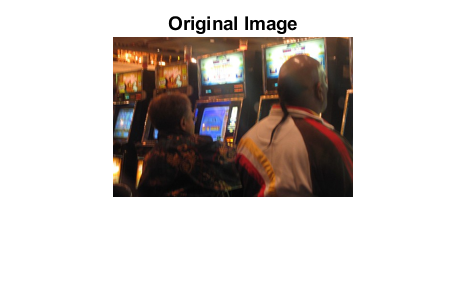

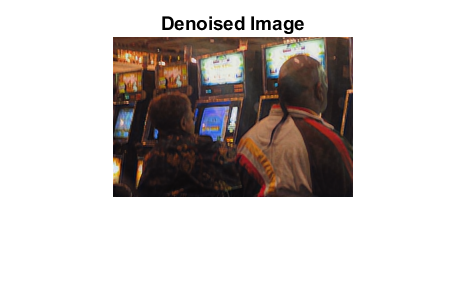

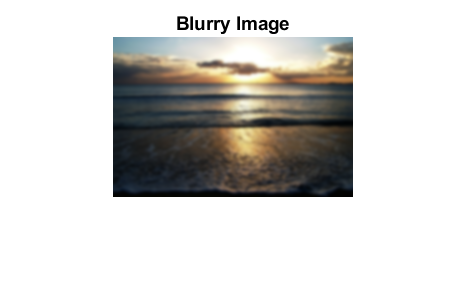

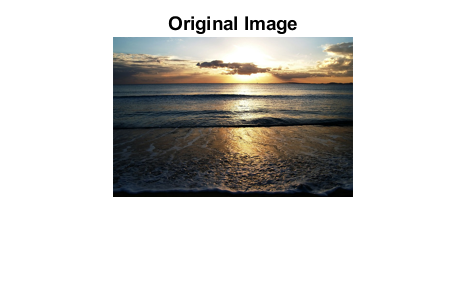

for k = 1:4
    testImage = testTrue.read();
    blurredImage = testBlur.read();
    figure; imshow(blurredImage);
    title('Blurry Image');
    
    figure; imshow(testImage);
    title('Original Image');
    Ideblurred = activations(net,blurredImage,'regressionOutput');
    figure;
    Iapprox = rescale(Ideblurred);
    Iapprox = im2uint8(Iapprox);
    imshow(Iapprox)
    title('Denoised Image')
    imwrite(testImage,['TrueImg' num2str(k) '.png'])
    imwrite(blurredImage,['BlurImg' num2str(k) '.png'])
    imwrite(Iapprox,['DeblurImg' num2str(k) '.png'])
end

function dataOut = addNoise(data)
    sigma = abs(random('Normal',0,5));
    if sigma > 0
        dataOut = imgaussfilt(data,sigma);
    else
        dataOut = data;
    end
end
function out = findWindow(im, s)
    ratio = s(2)/s(1);
    imSize = size(im);
    scale = min(imSize(1)*ratio,imSize(2));
    windowSize = floor([scale/ratio scale]);
    adjustment = floor(([imSize(1) imSize(2)]- windowSize)/2);
    out = im(1+adjustment(1):windowSize(1)+adjustment(1),1+adjustment(2):windowSize(2)+adjustment(2),:);
    out = imresize(out,s);
end